# **drawParabola**

Draw the arc of paramola

## Description

 Parametric equation of the parabola is

$x=4f{\;t}^2$,     $y=2f\;t$,    $0\le t<\infty$.

where *f is focal distance*are elispse semi axes.

## Syntax

drawParabola( t1, t2, f, xc, yc)

drawParabola( t1, t2, f, xc, yc, rot)

drawParabola( __, '-np', np)

drawParabola(__, LineSpec)

p = drawParabola(__)

## Description

drawParabola( t1, t2, f, xc, yc) draw the parabola with default number of points 360 and current line specification. 

drawParabola( t1, t2,f, xc, yc, rot) rotated by the angle *rot *in CCLW direction around 

drawParabola( __, LineSpec)  sets the line style, line width, and color.

drawParabola( __,'-np',np) set the number of points on the output curve.

p = drawParabola(__) returns structure with output data.

## Method

For calculation of the coordinates of the curve drawParabola call function **evalParabola( f,xc,yc,rot,t)  **which returns coordinates *x *and *y *of the curve at given parameters t . For usage of **evalParabola **see Example 1.

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**t1 **- initial parameter

**t2 **- final parameter

**f **- focal distance (real scalar)

**xc - **x-coordinate of the center (real scalar)

**yc **- y-coordinate of the center (real scalar)

### **Optional Input Argumnts**

**rot** - rotation angle about the center in degrees

**'-seg'** - draw  segment

### Optional Name-Value Pair Input Arguments

**'-np',** **np **- number of points along the curve ( scalar integer value > 2)

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.xk, p.yk - key points: 1=start,2=end,3=center

- p.th - tangent angle: 1=start,2=end 

- p.color - line color

## Examples

### Example 1

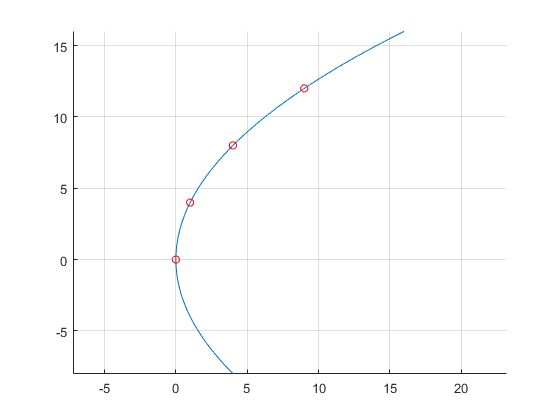

%Data 
f = 4;
% plot
figure
hold on
axis equal
[x,y] = evalParabola(f,0,0,0,linspace(-1,2));
plot(x,y)
[x,y] = evalParabola(f,0,0,0,[0, 0.5,1, 1.5]);
scatter(x,y,30,'r')
grid on

### Example 2

%Data 
xc = 0;
yc = 0;
f = 4;
t1 = -2;
t2 = 4;
figure
hold on
axis equal
P1 = drawParabola(t1,t2,f,1,1)

P1 = struct with fields:
       xk: [17 65 1]
       yk: [-15 33 1]
       th: [153.4349 14.0362]
    color: 'k'


P2 = drawParabola(t1,t2,f,xc,yc,45,'LineWidth',2,'Color','r','-np',10)

P2 = struct with fields:
       xk: [22.6274 22.6274 0]
       yk: [0 67.8823 0]
       th: [-161.5651 59.0362]
    color: [1 0 0]


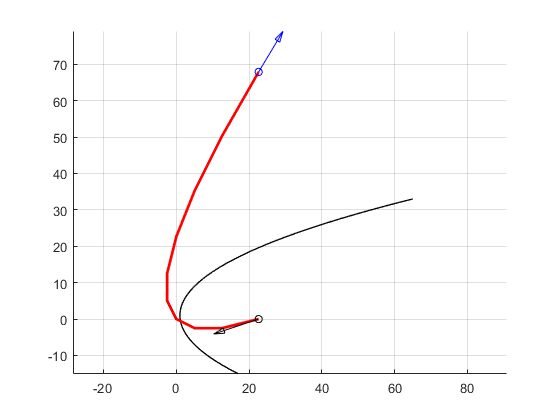

scatter(P2.xk(1),P2.yk(1),30,'k')
scatter(P2.xk(2),P2.yk(2),30,'b')
drawArrow(2,3,1.5,P2.xk(1),P2.yk(1),'-rtheta',13,P2.th(1),'k')
drawArrow(2,3,1.5,P2.xk(2),P2.yk(2),'-rtheta',13,P2.th(2),'b')
grid on

### Example 3

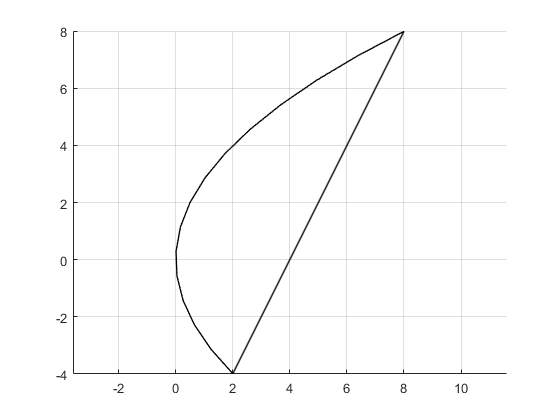

figure
hold on
axis equal
drawParabola(2,-1,2,0,0,'-seg','-np',15)
grid on

## **See Also**

## References